clc
clear all

fs = 48000

fs = 48000

DOA_pos = struct2cell(load("interpolated_mat_files\DOA_pos_interpolated.mat"));
P_pos = struct2cell(load('interpolated_mat_files\P_pos_interpolated.mat'));

DOA_neg = struct2cell(load("interpolated_mat_files\DOA_neg_interpolated.mat"));
P_neg = struct2cell(load('interpolated_mat_files\P_neg_interpolated.mat'));

DOA_inter = struct2cell(load("interpolated_mat_files\DOA_interpolated.mat"));
P_inter = struct2cell(load('interpolated_mat_files\P_interpolated.mat'));

DOA_added = struct2cell(load("interpolated_mat_files\DOA_add_interpolated.mat"));
P_added = struct2cell(load('interpolated_mat_files\P_add_interpolated'));

% original datapoint
load("rt40_mat_files\DOA_rt40.mat");
load("rt40_mat_files\pressure_rt40.mat");

for i=1:2
    for j=1:12
        P{j,i} = P{j,i}(200:2200);
    end
end

lengt_signal = 100

lengt_signal = 100

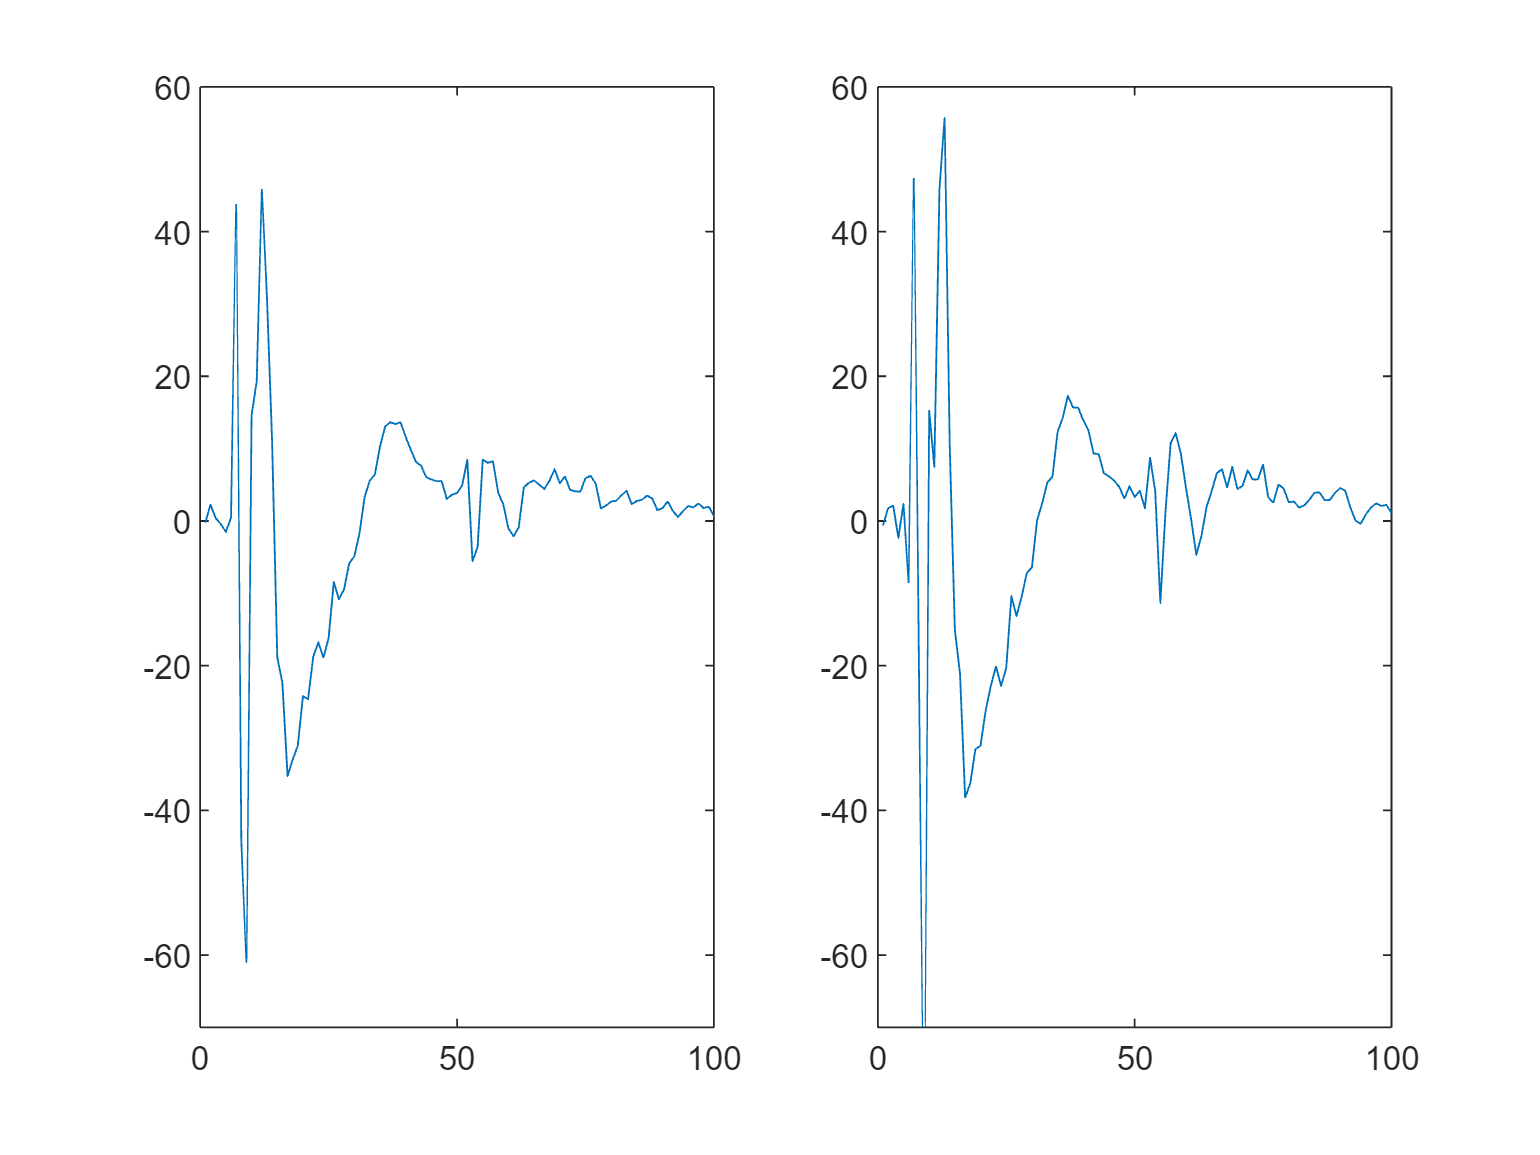

figure 
subplot(1,2,1)
plot(P{1,1})
axis([0 lengt_signal -70 60])
subplot(1,2,2)
plot(P{3,1})
axis([0 lengt_signal -70 60])

scale_P1 = zeros(length(P_inter{1,1}),1);
for i=1:length(scale_P1)
    if P{1,1}(i,1) > 0
        scale_P1(i,1) = 1;
    elseif P{1,1}(i,1) < 0
        scale_P1(i,1) = -1;
    else
        scale_P1(i,1) = 0
    end
end

scale_P3 = zeros(length(P_inter{1,1}),1);
for i=1:length(scale_P3)
    if P{3,1}(i,1) > 0
        scale_P3(i,1) = 1;
    elseif P{3,1}(i,1) < 0
        scale_P3(i,1) = -1;
    else
        scale_P3(i,1) = 0
    end
end

P_interpolated_scaled_P1{1,1} = scale_P1(1:length(P_inter{1,1}),1) .* (2*P_inter{1,1}(:,1));
DOA_inter{1,1} = DOA_inter{1,1}(1:length(P_interpolated_scaled_P1{1,1}),:);
P_interpolated_scaled_P3{1,1} = scale_P3(1:length(P_inter{1,1}),1) .* (2*P_inter{1,1}(:,1));

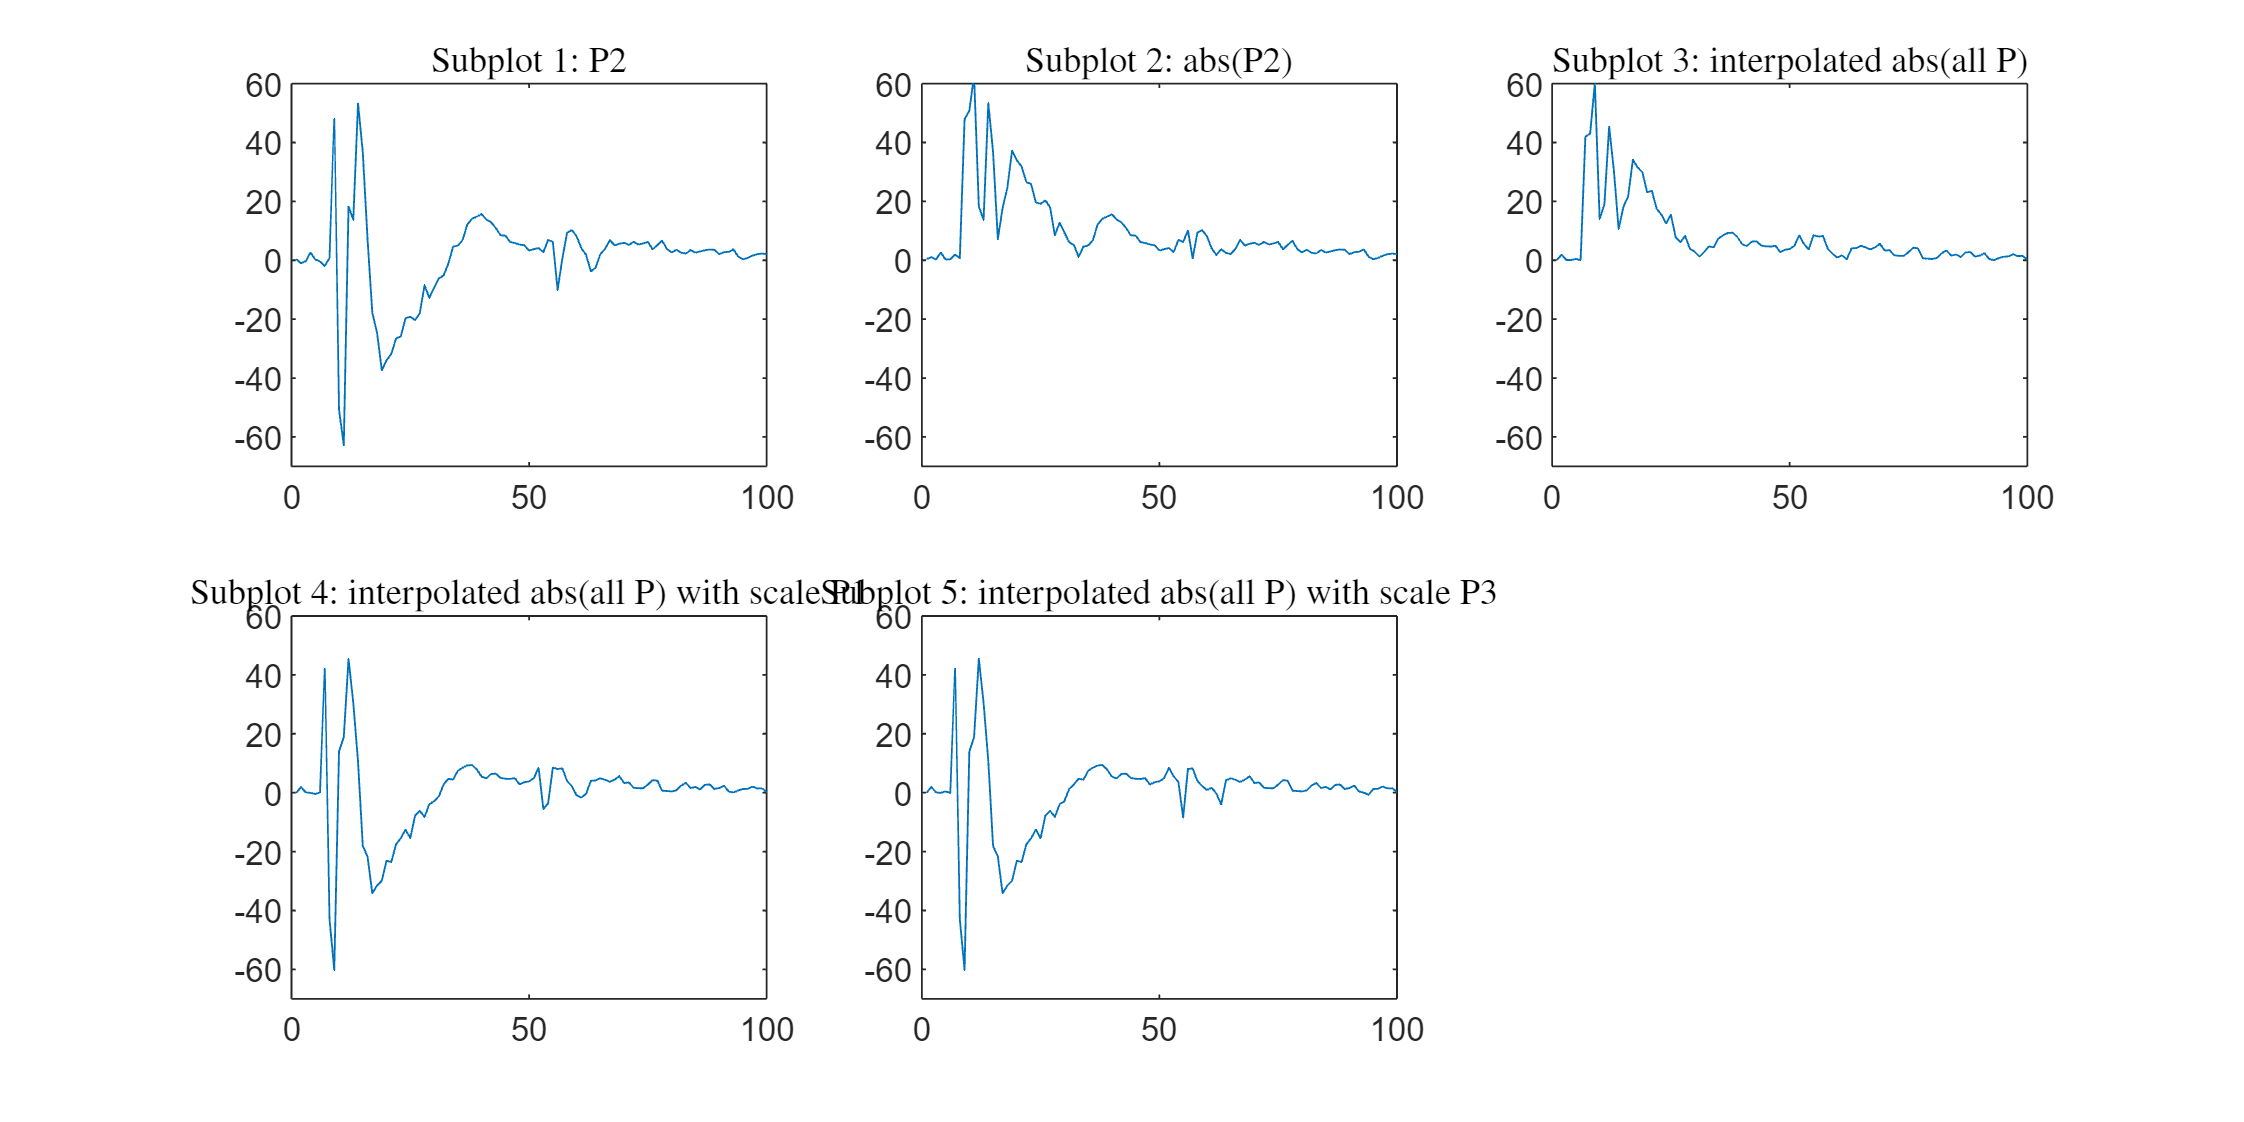

figure('Position', [100, 100, 2000, 1000])

subplot(2,3,1)
plot(P{2,1})
axis([0 lengt_signal -70 60])
title('Subplot 1: P2')

subplot(2,3,2)
plot(abs(P{2,1}))
axis([0 lengt_signal -70 60])
title('Subplot 2: abs(P2)')

subplot(2,3,3)
plot(2*P_inter{1,1})
axis([0 lengt_signal -70 60])
title('Subplot 3: interpolated abs(all P)')

subplot(2,3,4)
plot(P_interpolated_scaled_P1{1,1})
axis([0 lengt_signal -70 60])
title('Subplot 4: interpolated abs(all P) with scale P1')

subplot(2,3,5)
plot(P_interpolated_scaled_P3{1,1})
axis([0 lengt_signal -70 60])
title('Subplot 5: interpolated abs(all P) with scale P3')

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 48000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','ESAT STADIUS Lab','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 48000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'ESAT STADIUS Lab'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')
% parameterVisualization(P(2,1), v);
% parameterVisualization(P_inter, v);
% parameterVisualization(P_pos, v);
% parameterVisualization(P_neg, v);
% parameterVisualization(P_added, v);

Started time-frequency visualization.


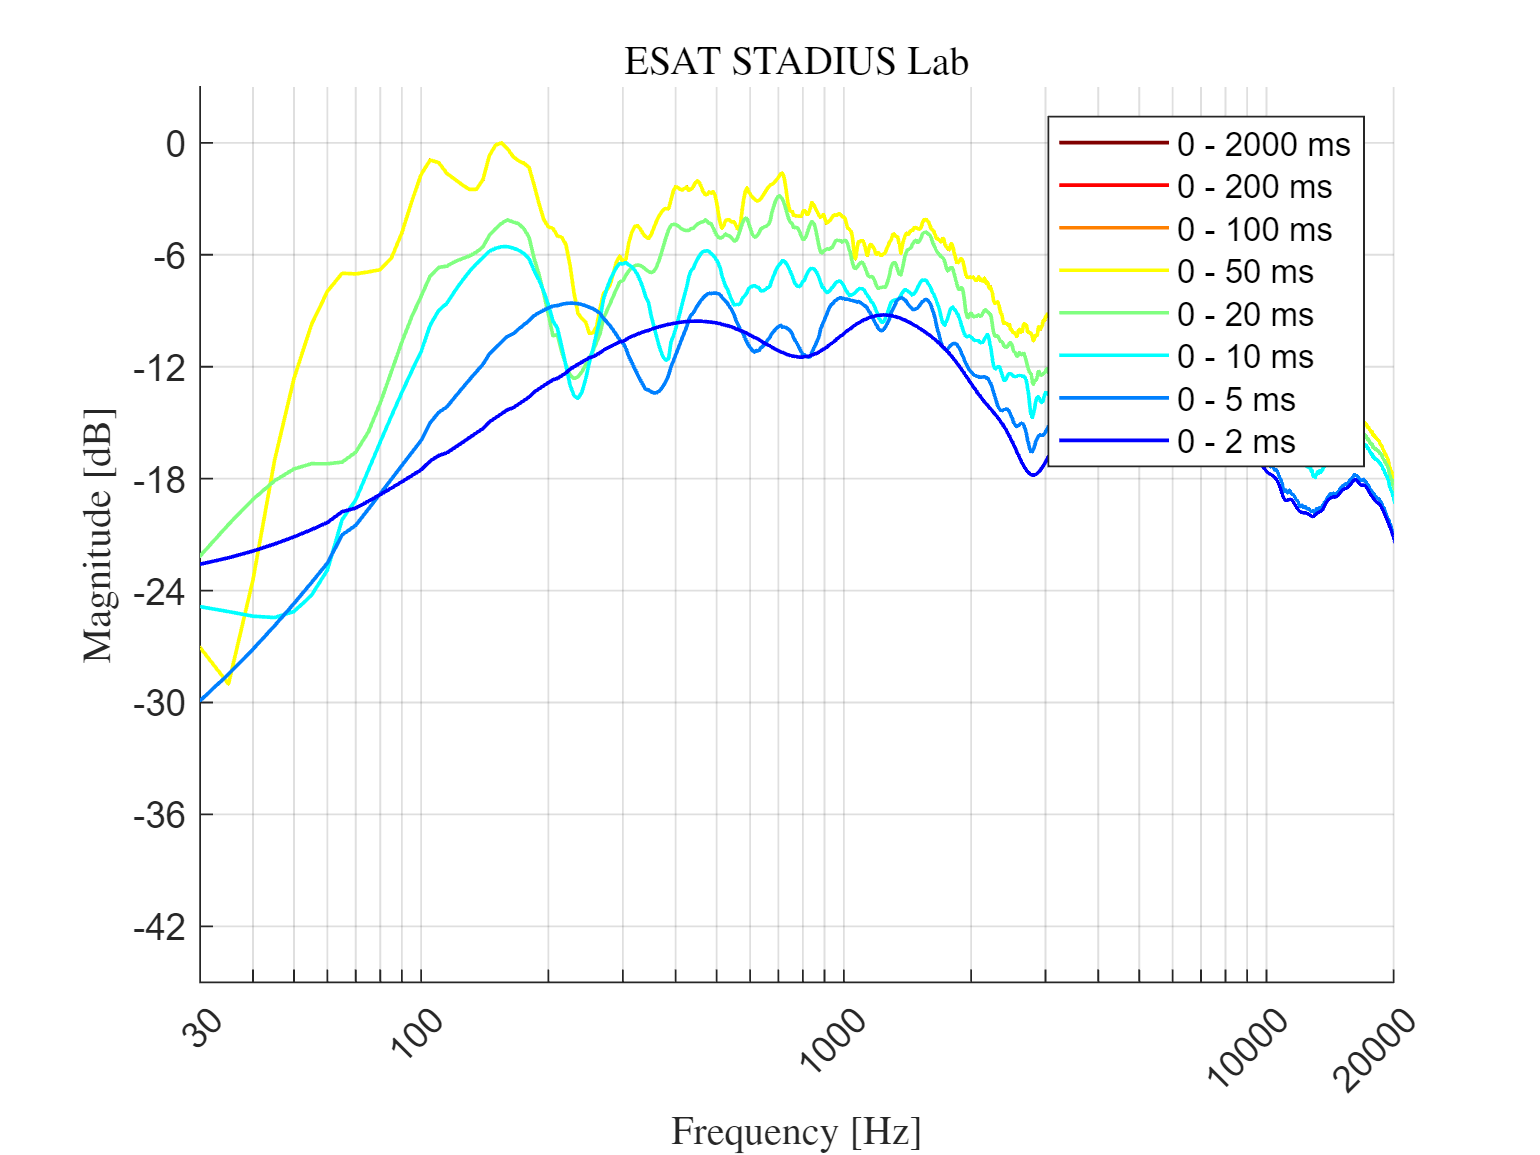

Ended time-frequency visualization in 0.79563 seconds.


timeFrequencyVisualization(P(2,1), v);

Started time-frequency visualization.


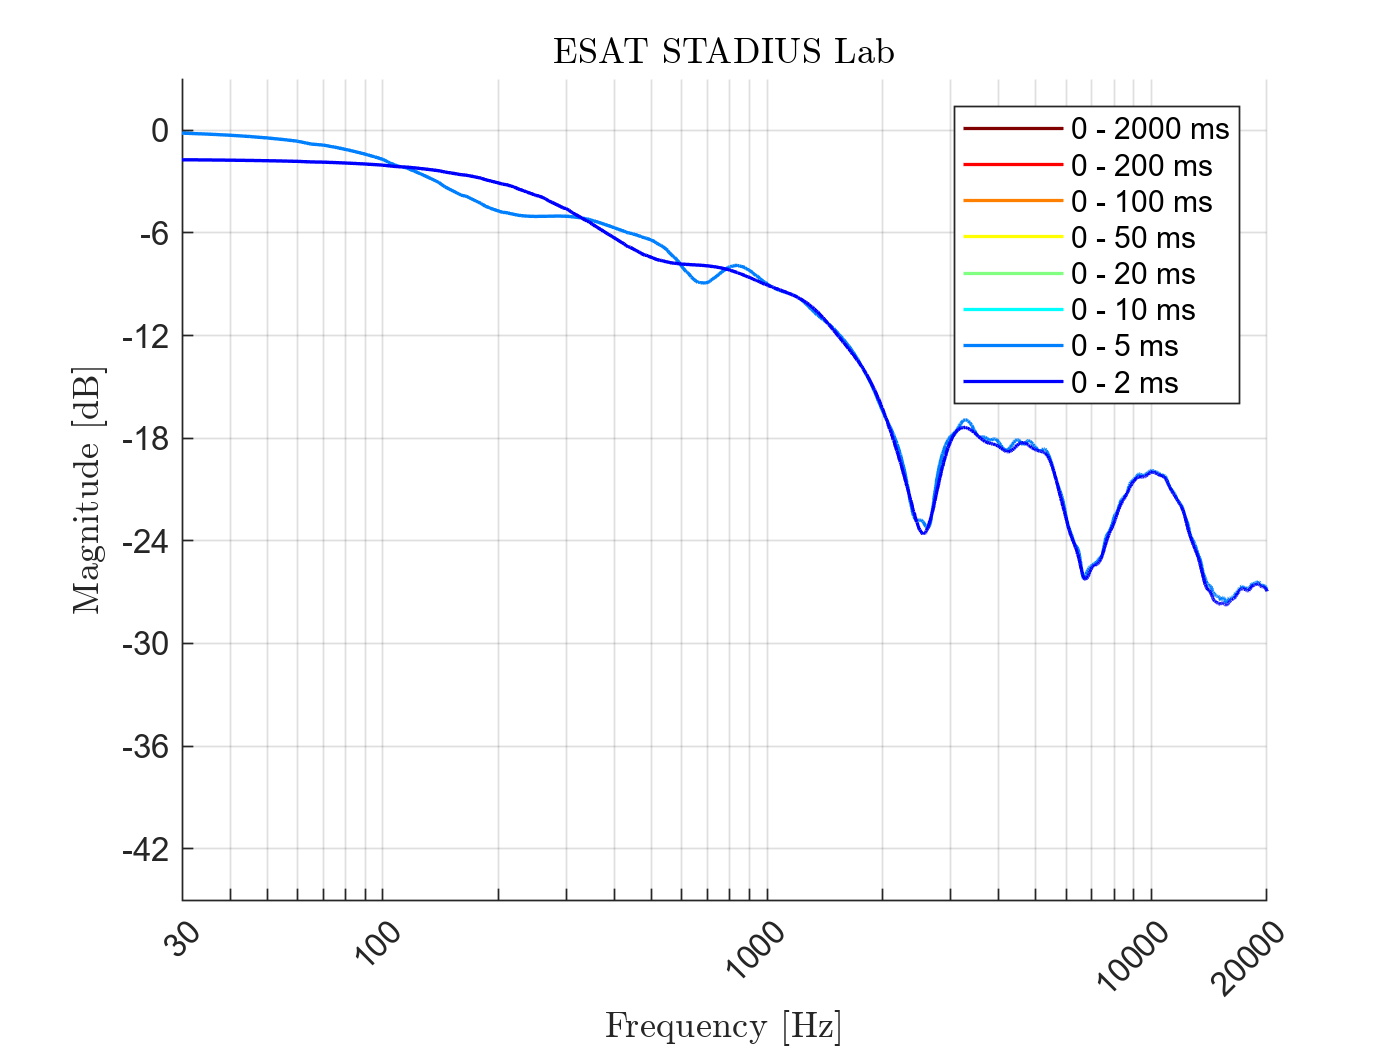

Ended time-frequency visualization in 0.82147 seconds.


timeFrequencyVisualization(P_inter, v);

Started time-frequency visualization.


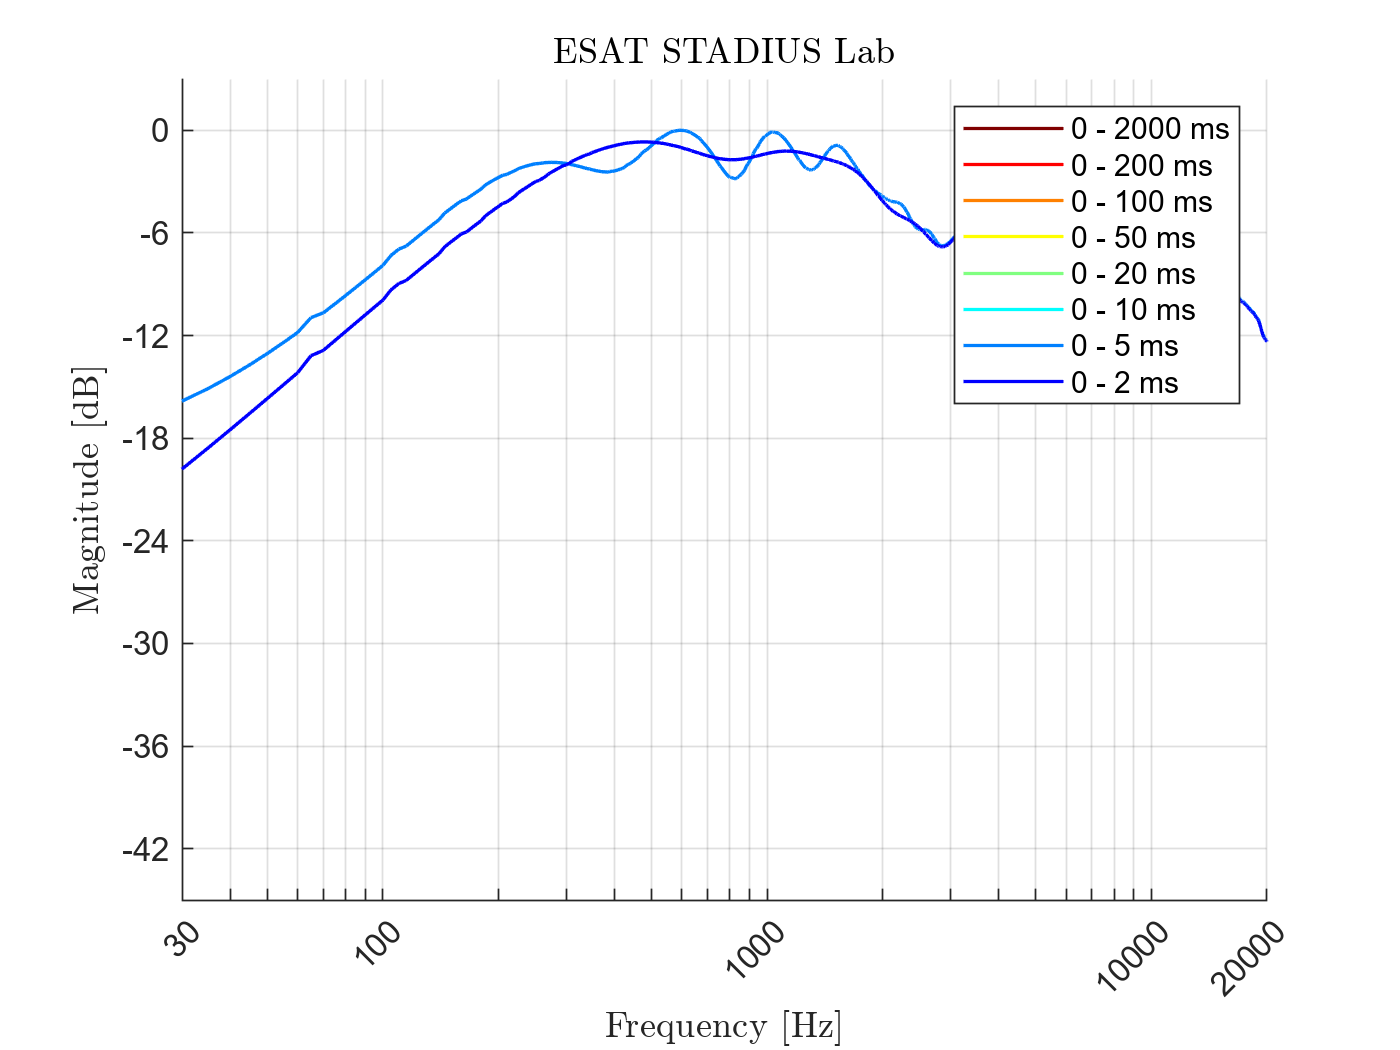

Ended time-frequency visualization in 0.49281 seconds.


timeFrequencyVisualization(P_interpolated_scaled_P1, v);

Started time-frequency visualization.


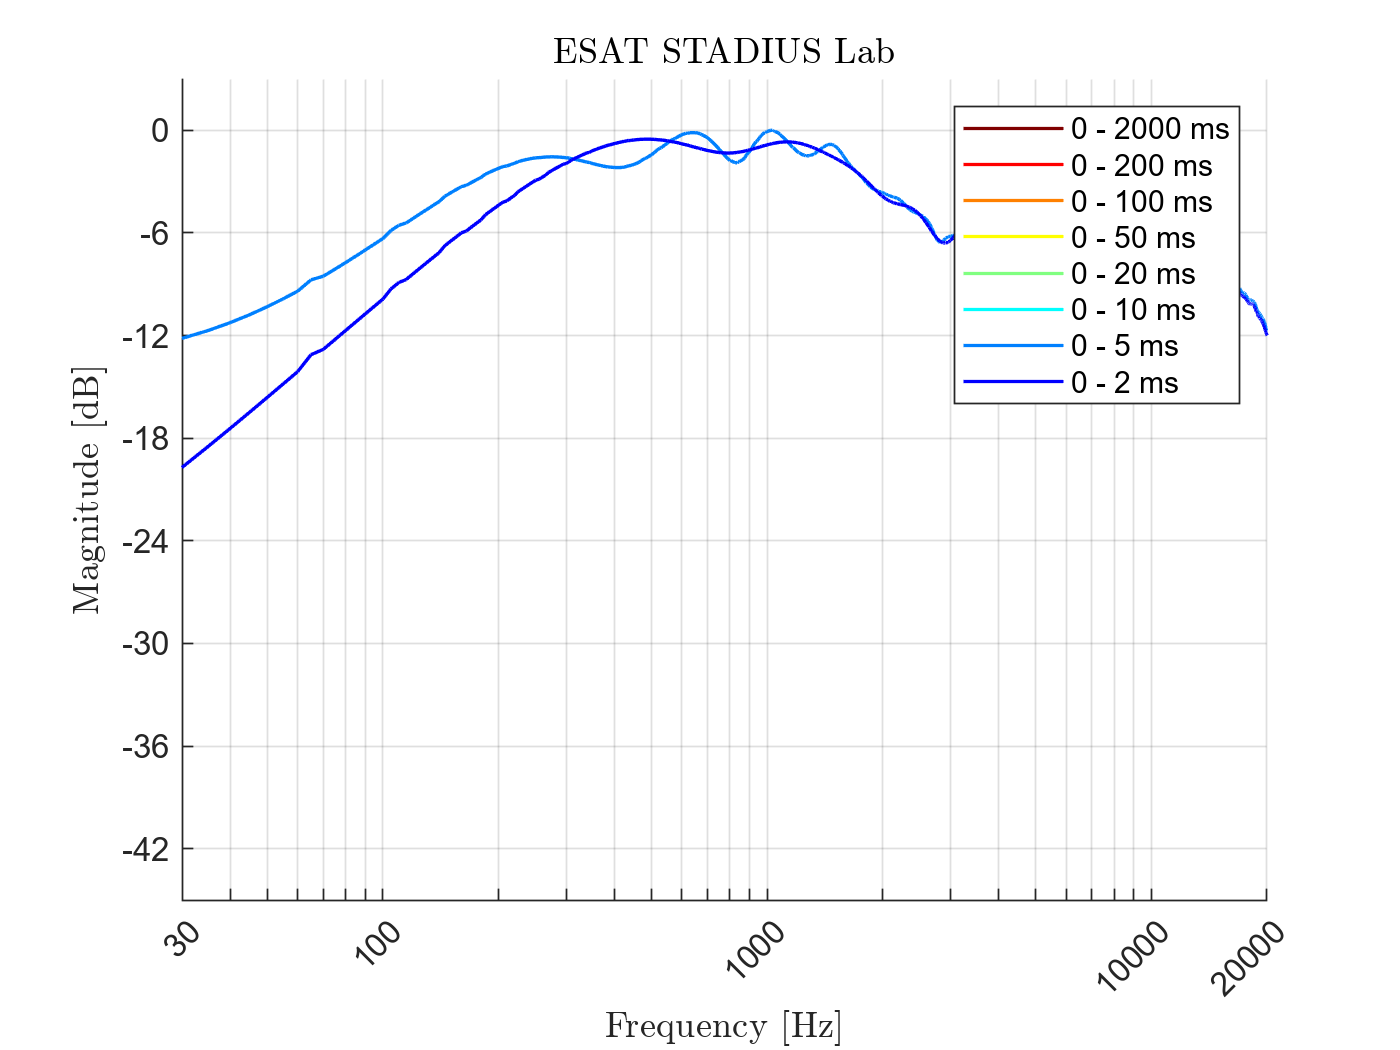

Ended time-frequency visualization in 0.43001 seconds.


timeFrequencyVisualization(P_interpolated_scaled_P3, v);

Started spatio-temporal visualization.


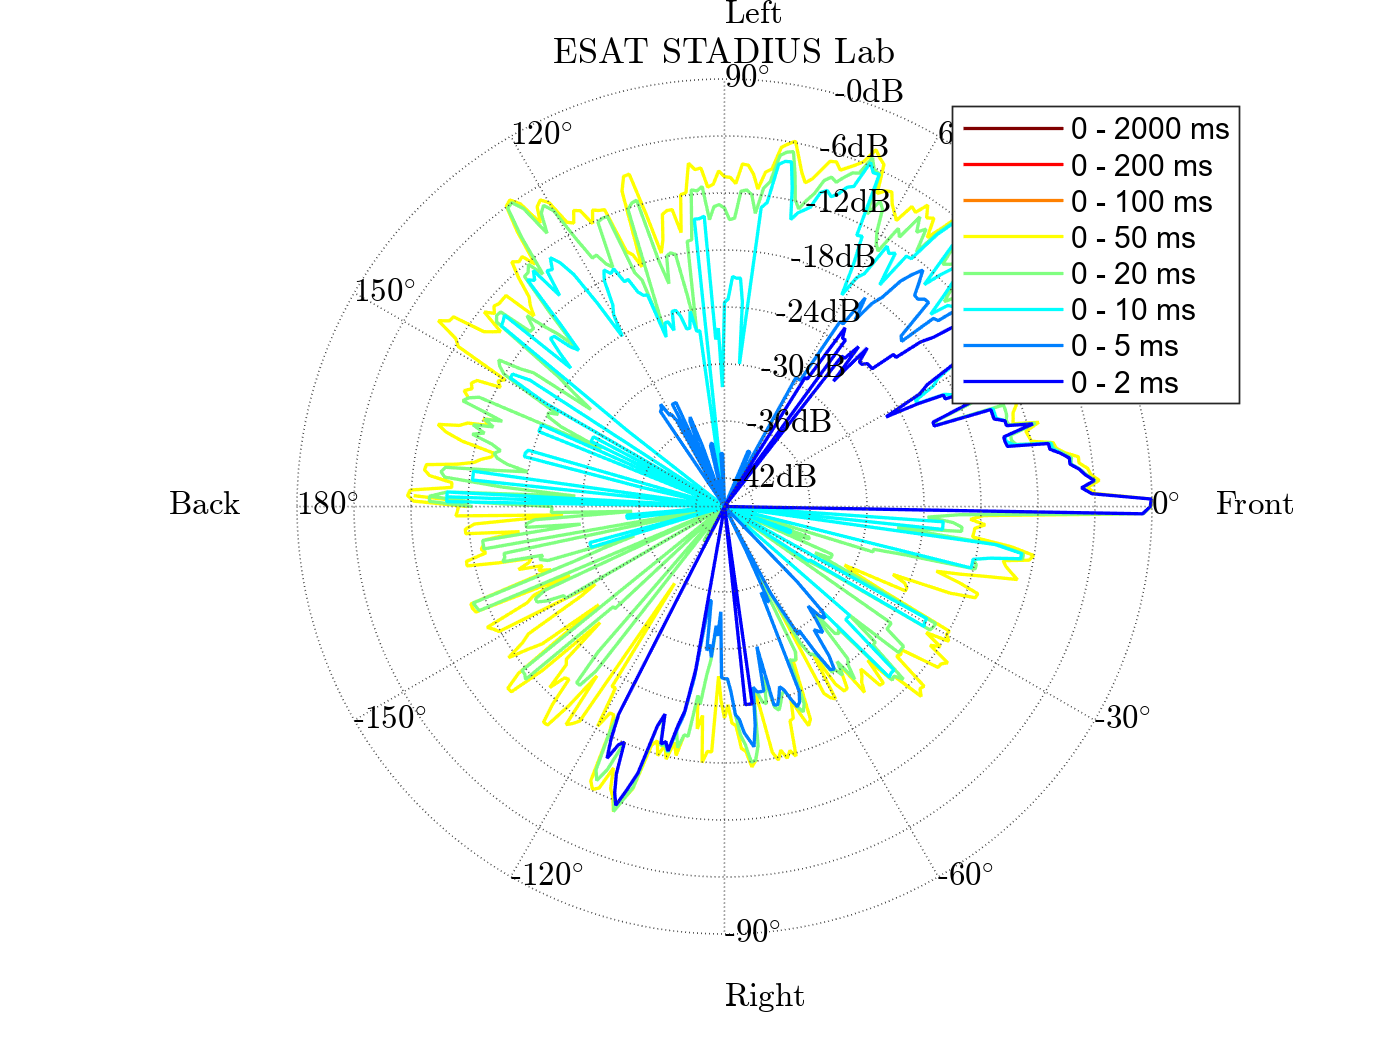

Ended spatio-temporal visualization in 0.43067 seconds.


ans = -2

v.plane = 'lateral';
% Original second measurement
spatioTemporalVisualization(P(2,1), DOA(2,1), v)

Started spatio-temporal visualization.


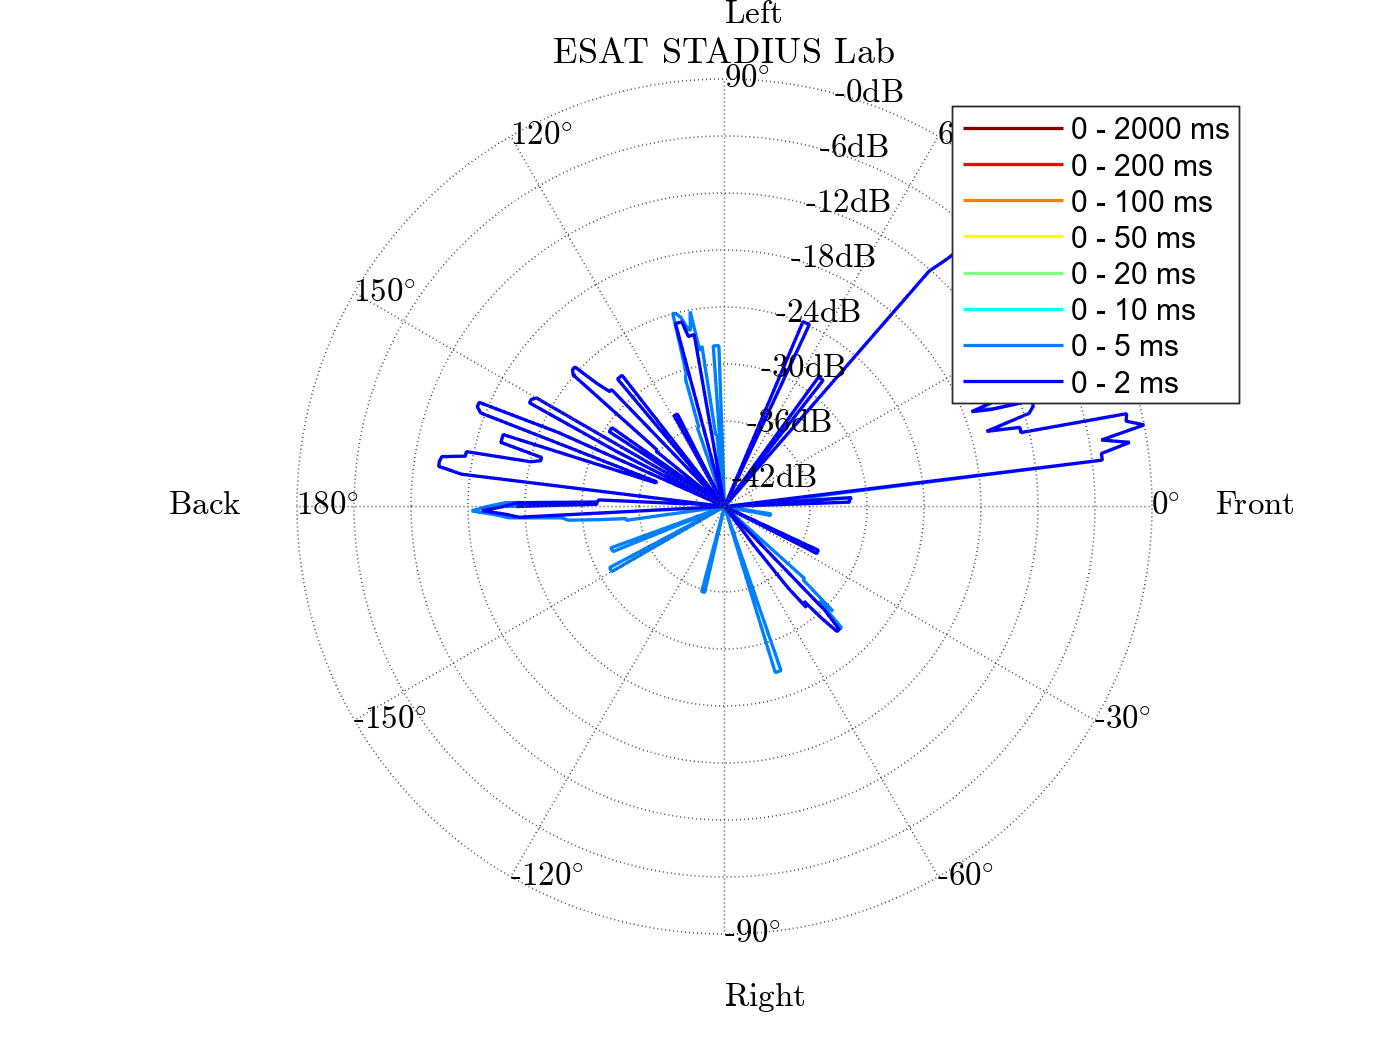

Ended spatio-temporal visualization in 0.24046 seconds.


ans = -12

% Interpolated
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


Ended spatio-temporal visualization in 0.25575 seconds.


ans = -12

spatioTemporalVisualization(P_interpolated_scaled_P1, DOA_inter, v)

Started spatio-temporal visualization.


Ended spatio-temporal visualization in 0.32377 seconds.


ans = -12

spatioTemporalVisualization(P_interpolated_scaled_P3, DOA_inter, v)

Started spatio-temporal visualization.


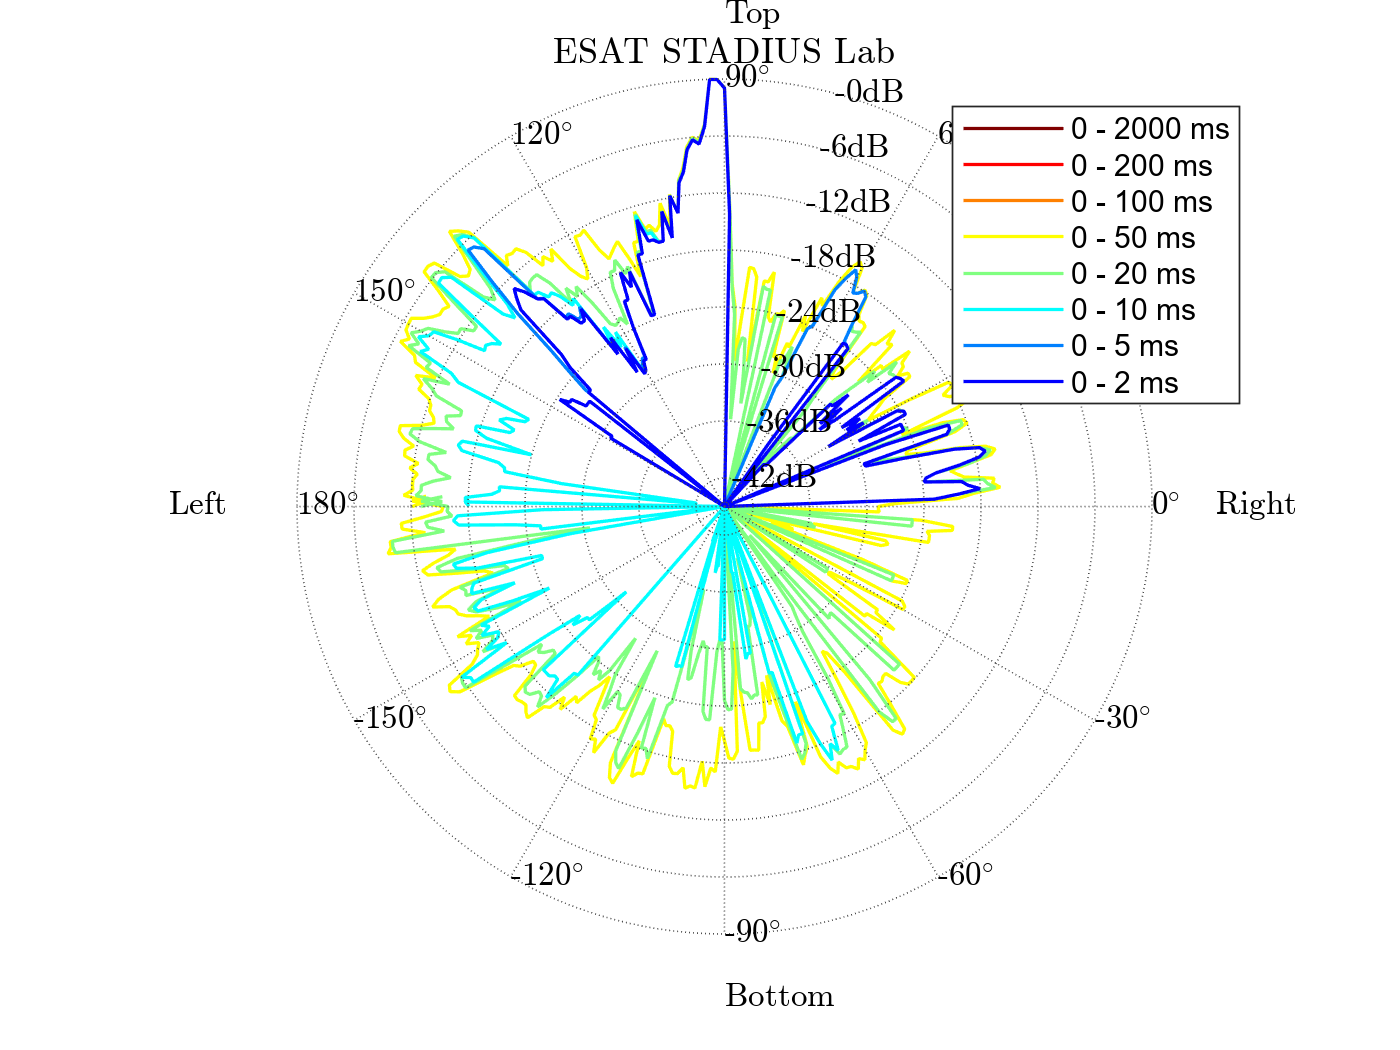

Ended spatio-temporal visualization in 0.29509 seconds.


ans = -93

v.plane = 'transverse';
% Original
spatioTemporalVisualization(P(2,1), DOA(2,1), v)

Started spatio-temporal visualization.


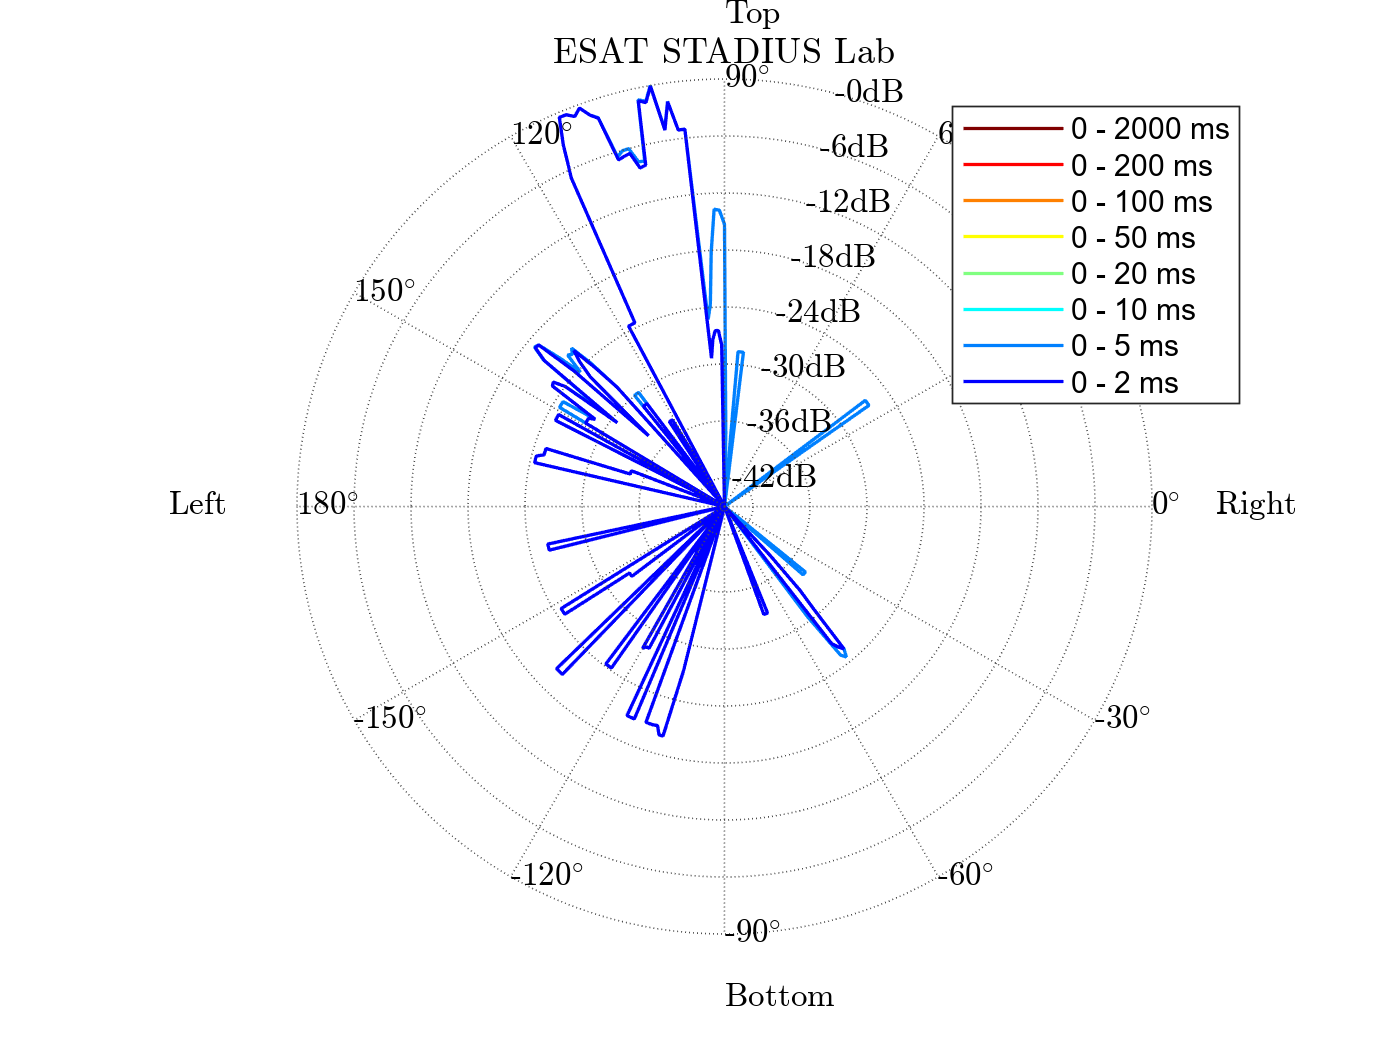

Ended spatio-temporal visualization in 0.3068 seconds.


ans = -101

% Interpolated
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


Ended spatio-temporal visualization in 0.26121 seconds.


ans = -101

spatioTemporalVisualization(P_interpolated_scaled_P1, DOA_inter, v)

Started spatio-temporal visualization.


Ended spatio-temporal visualization in 0.27473 seconds.


ans = -101

spatioTemporalVisualization(P_interpolated_scaled_P3, DOA_inter, v)

Started spatio-temporal visualization.


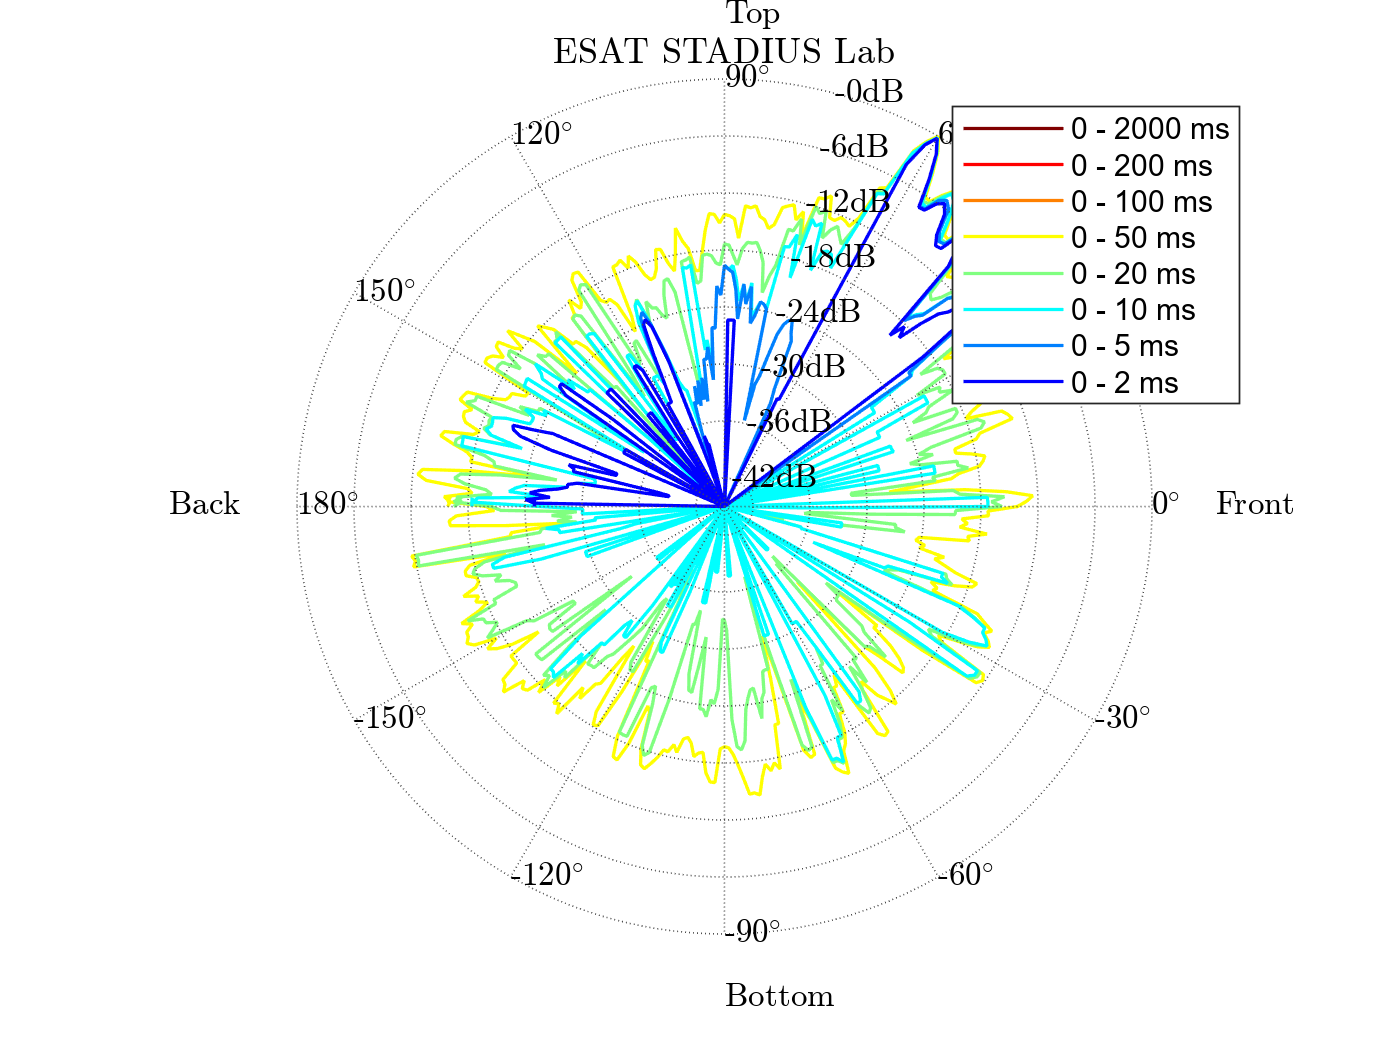

Ended spatio-temporal visualization in 0.27209 seconds.


ans = -61

v.plane = 'median';
% Original
spatioTemporalVisualization(P(2,1), DOA(2,1), v)

Started spatio-temporal visualization.


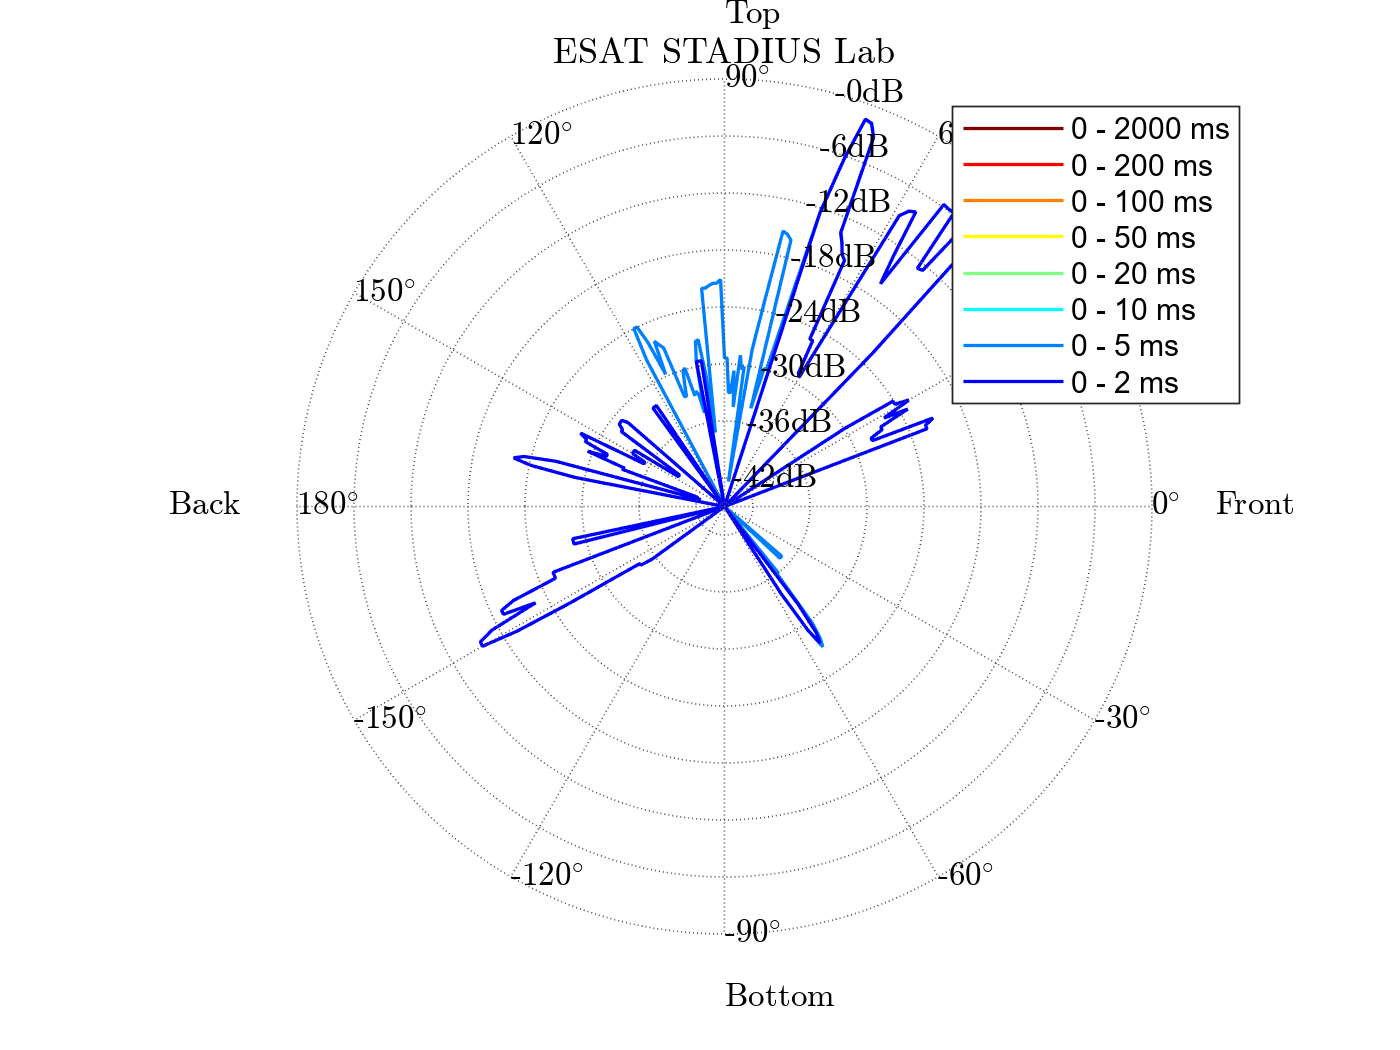

Ended spatio-temporal visualization in 0.35082 seconds.


ans = -50

% Interpolated
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


Ended spatio-temporal visualization in 0.3102 seconds.


ans = -50

spatioTemporalVisualization(P_interpolated_scaled_P1, DOA_inter, v)

Started spatio-temporal visualization.


Ended spatio-temporal visualization in 0.28435 seconds.


ans = -50

spatioTemporalVisualization(P_interpolated_scaled_P3, DOA_inter, v)